# Design Matlab MPC object

clear;

## Plant model

% Sampling period
Ts = 1;

% Parameters
% Shipping delay between the Factory and Retailer [time units]
thetap2 = 3;  

% Retail inventory model
% input u(k) : orders to factory at time k
% output y(k) : inventory level at end of time k
%G = tf(1, [1 -1], Ts, 'IODelay', thetap2, 'Variable', 'z^-1');
%model_ = ss(G);
%model_ = absorbDelay(model_);
%model_ = minreal(model_);

% Factory production lead time [time units]
%thetap1 = 3;

% Factory inventory model
% input u(k) : production starts at time k
% output y(k) : inventory level at end of time k
%G_ = tf(1, [1 -1], Ts, 'IODelay', thetap1, 'Variable', 'z^-1');


% This function produces the equivalent model but with
% 'nicer' coefficients.
[model, G] = prod_inv_sys_dt(thetap2, Ts, 'simple')

model =
 
  A = 
       x1  x2  x3
   x1   1   1   0
   x2   0   0   1
   x3   0   0   0
 
  B = 
       u1  u2
   x1   0  -1
   x2   0   0
   x3   1   0
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1  u2
   y1   0  -1
 
Sample time: 1 seconds
Discrete-time state-space model.


G =
 
  From input 1 to output:
              1
  z^(-3) * --------
           1 - z^-1
 
  From input 2 to output:
     -1
  --------
  1 - z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.




% Verify both models are the same
% y = impulse(model, 10);
% y_ = impulse(model_, 10);
% assert(all(abs(y - y_) < 1e-12))

n = length(model.A);
nu = size(model.B,2);
ny = size(model.C,1);

## Design MPC Controller

mpcverbosity off;
% Define type of input signals for the plant:
%  MV, Manipulated: input channels 
%  MD, Measured Disturbances: input channels 
%  UD, Unmeasured Disturbances: input channels 
%  MO, Measured Outputs: output channels 
%  UO, Unmeasured Outputs: output channels
model = setmpcsignals(model,'MV',1,'MD',2,'MO',1);
% Create the controller object with sampling period (all other parameters by default)
mpcobj = mpc(model,Ts);
%


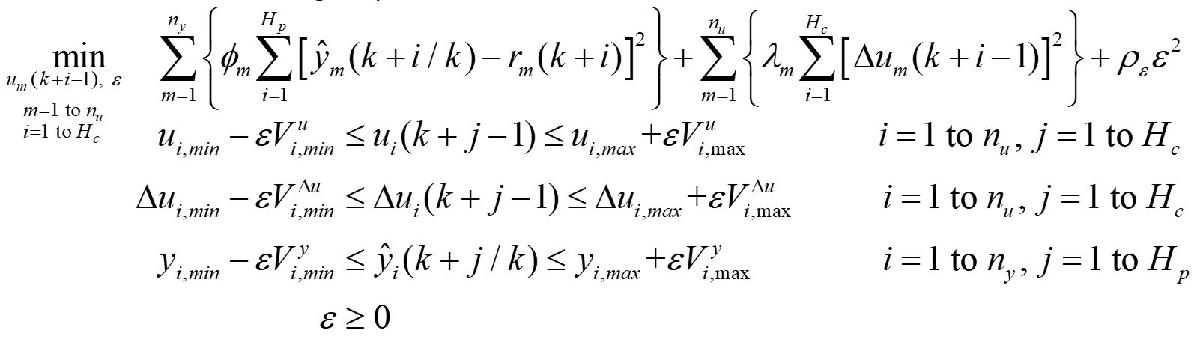

% Main MPC parameters:

% Operating points
u_op = [10000; 10000];
y_op = 15000;
mpcobj.model.Nominal.U=u_op;
mpcobj.model.Nominal.Y=y_op;
%
%Prediction and control horizons
mpcobj.PredictionHorizon = 20;
mpcobj.ControlHorizon = 2;
%
%constraints and scaling for Mvs
mpcobj.MV = struct('Min',{0},'Max',{inf}, ... % u_min u_max
                   'RateMin',{-inf},'RateMax',{inf}, ... % deltau_min deltau_max
                   'RateMinECR',{0},'RateMaxECR',{0}, ... % V^deltau_min V^deltau_max (0 = hard constraints)
                   'MinECR',{0},'MaxECR',{0}, ... % V^u_min V^u_max (0 = hard constraints)
                   'ScaleFactor',{1000}); % range of u    
%
mpcobj.DisturbanceVariables.ScaleFactor = 1000;

%constraints and scaling for OVs (OV = OutputVariables = MO + UO - here we only have MOs)
mpcobj.OV = struct('Min',{0},'Max',{inf}, ... %y_min y_max 
                   'MinECR',{1},'MaxECR',{1}, ...% V^y_min V^y_max (1 = soft constraints)
                   'ScaleFactor',{1000}); ... % range of y     
% Weights
mpcobj.Weights.OutputVariables = 1; % phi
mpcobj.Weights.ManipulatedVariablesRate = 5; % lambda
mpcobj.Weights.ECR = 1e5; % rho_epsilon
%

## Design Observer

Some possible ways: 

1: Default observer with input disturbances = integrators driven by white noise with unitary standard deviations 

2: Default observer with integrators driven by white noise with selected standard deviations 

3: Design of our own Luenberger observer 

4: Design of our own steady-state Kalman filter:

observer=0;
% Get output scaling factors
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%sy=[mpcobj.OV(1).ScaleFactor,mpcobj.OV(2).ScaleFactor];
switch observer
    case 1
        setindist(mpcobj,'integrators'); % input disturbances are integrated white noises
    case 2
        % 2a: modindist: model of input disturbances driven by white noise
        % identical to case 1
        modindist=[tf(1,[1 0]) 0; 0 tf(1,[1 0])]; 
        % 2b: faster input disturbance 1 (t = 800) rejection
        %modindist=[tf(5,[1 0]) 0; 0 tf(1,[1 0])]; 
        % 2c: faster input disturbance 2 (t = 1200) rejection
        %modindist=[tf(1,[1 0]) 0; 0 tf(5,[1 0])]; 
        % 2d: both faster
        %modindist=[tf(5,[1 0]) 0; 0 tf(5,[1 0])]; 
        setindist(mpcobj,'model',modindist);  
    case 3
        % augmented model with integrators
        Aaug=[model.A model.B(:,1:nu); zeros(nu,n) eye(nu)];
        Caug=[model.C zeros(ny,nu)];
        %
        % poles_obs: poles of the estimation error dynamics  
        poles_obs=zeros(1,n+nu);
        for i=1:n+nu
            poles_obs(i)=1-i*0.015; % slower disturbance rejection, less sensitive to noise
        end
        %for i=1:n+ny
        %    poles_obs(i)=0.95-i*0.015; % faster disturbance rejection, more sensitive to noise
        %end
        % not obvious to know which modes affect which outputs: we would
        % need a modal observer
        %
        Kpred = place(Aaug',Caug',poles_obs)';
        setEstimator(mpcobj,Kpred);
    case 4
        % augmented model with integrators
        Aaug=[model.A model.B(:,1:nu); zeros(nu,n) eye(nu)];
        Baug=[model.B(:,1:nu); zeros(nu,nu)];
        Caug=[model.C zeros(ny,nu)];
        Daug=[zeros(ny,nu)];       
        %
        % Matrices G and H: seek help kalman 
        G=eye(size(Baug,1));
        H=zeros(size(Caug,1),size(Baug,1));
        %
        % Covariance matrices
        R=0.1*eye(ny); % Measurement noise
        % Q: covariance matrix, process noise
        Q=blkdiag(0.1*eye(n-nu),0.001,0.001);      
        %Q=blkdiag(eye(n-nu),0.001,1); 
        %Q=blkdiag(eye(n-nu),1,0.001); 
        %Q=blkdiag(eye(n-nu),1,1); 
        %
        [~,Kpred] = kalman(ss(Aaug,[Baug G],Caug,[Daug H],Ts),Q,R);
        setEstimator(mpcobj,Kpred);
end

% The creation of the model predictive controller object «mpcobj» is now complete:
mpcobj

 
MPC object (created on 01-Oct-2023 22:06:36):
---------------------------------------------
Sampling time:      1 (seconds)
Prediction Horizon: 20
Control Horizon:    2

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  3 states  |
                                      |            |-->  1 measured output(s)
      1  measured disturbance(s)   -->|  2 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Indices:
  (input vector)    Manipulated variables: [1 ]
                    Measured disturbances: [2 ]
  (output vector)        Measured outputs: [1 ]

Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: 0
    Man

## Simulation with Simulink

Tstop = 250;          % simulation time
t = 0:Ts:Tstop;       % time vector
N = length(t);        % number of simulation steps
%

% Initial conditions
I_init = 15000;  % inventory
PA_init = 10000;  % production

% Reference – inventory target
r = 15000 * ones(N, 1);

% Input disturbance - demand
step_changes = [
    0 10000 
   50 11000 
  100 12000 
  150 11000
  200 10000
];
df = make_step_sequence(t, step_changes)';

% Simulink inputs
r_sim = [t' r];
df_sim = [t' df];
%dy_sim = [t' dy];
open('prodinvsys_sim_mpc.slx');
sim('prodinvsys_sim_mpc.slx');

return

# ADVANCED CODE FOR GEL-7029:

## Simulate Closed-Loop Response Using the SIM Command

% Specify simulation parameters.
SimOptions = mpcsimopt(mpcobj);                       
SimOptions.UnmeasuredDisturbance = du;
SimOptions.OutputNoise = dy;
SimOptions.ShowOutputNoise = 1;    % Does not work...
%
% Run the closed-loop simulation and save the results.
[y,tsim,u,xp] = sim(mpcobj,N,r,[],SimOptions);
%
% Plot results.
figure(1);
subplot(211)
plot(tsim,y,'k-',tsim,r,'r:','linewidth',2)
title('Set-points and CVs (sim)');
text(300,40,'Problem with sim'); % The same problem is present when simulating inside mpcDesigner (it uses sim command)
text(300,37,'with output'); 
text(300,34,'disturbances');
grid
subplot(212)
stairs(tsim,u,'k-','linewidth',2)
title('MVs');
grid

## Simulate MPC with MPCMOVE (for loop)

% First get the discrete-time state-space matrices of the plant.
[A,B,C,D] = ssdata(model);
x = zeros(n,1);                 % Initial state of the plant
u = zeros(nu,1);                % Initial MVs
xmpc = mpcstate(mpcobj);    % Initial state of the MPC controller
%
% Store the closed-loop MPC trajectories in arrays YY,UU.
YY=zeros(2,N);
UU=zeros(2,N);
%
% Create simulation loop
for i=1:N
    % Plant equation: output
    y = C*x + dy(i,:)' + mpcobj.model.Nominal.Y; 
    YY(:,i) = y;
    %     
    % Compute MPC action
    [u, predinfo] = mpcmove(mpcobj,xmpc,y,r(i,1:2)',[]);
    %
    % Plant equations: state update
    x = A*x + B*([u; du(i,:)'] - mpcobj.model.Nominal.U); 
    UU(:,i) = u;
end

% Plot results.
figure(2);
subplot(211)
plot(t,YY,'k-',t,r,'r:','linewidth',2)
grid
title('Set-points and CVs (mpcmove)');
subplot(212)
stairs(t',UU')
stairs(t',UU','k-','linewidth',2)
grid
title('MVs');